# GFM-GWT GSC DC-Link Power-Loop Screening

Screens DC-voltage-loop bandwidth and feedback polarity before using GFM-GWT in a causal torsional comparison. The target is to avoid a DC controller pole dominating conclusions about the mechanical mode.

close all
clear
clc

this_dir = fileparts(mfilename('fullpath'));
if isempty(this_dir)
    this_dir = pwd;
end
cd(this_dir);
addpath(genpath('D:\apps\matlab\R2024b\bin\matpower8.0'));
run("Parameters.m");
this_dir = pwd;
base_params = load("Parameters.mat");
model_file = load("Unified_WT_PMSG_GFM_GWT.mat");
model = model_file.Unified_GFMI;
mpopt = mpoption('verbose', 0, 'out.all', 0);

bandwidth_hz = logspace(-3, 1, 50).';
polarity = [1; -1];
screening = table();
for p = 1:numel(polarity)
    for k = 1:numel(bandwidth_hz)
        params = base_params;
        params.w_dc_gwt = 2*pi*bandwidth_hz(k);
        params.k_pdc_gwt = polarity(p) * 2*params.zeta_dc_gwt*params.w_dc_gwt*params.C_dc*params.V_dc0;
        params.k_idc_gwt = polarity(p) * params.w_dc_gwt^2*params.C_dc*params.V_dc0;
        A = make_A(model, mpopt, params);
        metric = torsion_metric(A, model.X_stac);
        row = table(polarity(p), bandwidth_hz(k), params.k_pdc_gwt, params.k_idc_gwt, ...
            metric.MaxReal, metric.DominantFrequencyHz, metric.Sigma, metric.FrequencyHz, metric.DampingRatio, ...
            'VariableNames', {'Polarity', 'BandwidthHz', 'Kp', 'Ki', 'MaxReal', 'DominantFrequencyHz', ...
            'TorsionSigma', 'TorsionFrequencyHz', 'TorsionDampingRatio'});
        screening = [screening; row]; %#ok<AGROW>
    end
end

result_dir = fullfile(this_dir, 'Control_Mode_Comparison_Results');
if ~exist(result_dir, 'dir')
    mkdir(result_dir);
end
writetable(screening, fullfile(result_dir, 'gfm_gwt_dvc_screening.csv'));
[~, best_index] = min(screening.MaxReal);
best = screening(best_index, :);
fprintf('\nBest GFM-GWT GSC-DVC screening point\n');


Best GFM-GWT GSC-DVC screening point


disp(best);

    Polarity    BandwidthHz      Kp         Ki        MaxReal     DominantFrequencyHz    TorsionSigma    TorsionFrequencyHz    TorsionDampingRatio
    ________    ___________    ______    ________    _________    ___________________    ____________    __________________    ___________________

       1         0.0065513     1.7288    0.050832    -0.010132             0               -0.15303            1.9973               0.012194      



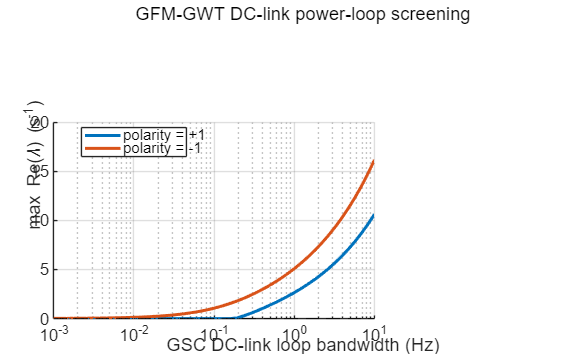


fig = figure('Color', 'w', 'Position', [140 140 660 400]);
ax = axes(fig);
ax.Toolbar.Visible = 'off';
hold(ax, 'on');
for p = 1:numel(polarity)
    rows = screening(screening.Polarity == polarity(p), :);
    semilogx(ax, rows.BandwidthHz, rows.MaxReal, 'LineWidth', 1.8, ...
        'DisplayName', sprintf('polarity = %+d', polarity(p)));
end
yline(ax, 0, 'k--', 'HandleVisibility', 'off');
set(ax, 'XScale', 'log');
grid(ax, 'on');
xlabel(ax, 'GSC DC-link loop bandwidth (Hz)');
ylabel(ax, 'max Re(\lambda) (s^{-1})');
title(ax, 'GFM-GWT DC-link power-loop screening');
legend(ax, 'Location', 'best');
exportgraphics(fig, fullfile(result_dir, 'gfm_gwt_dvc_screening.png'), 'Resolution', 300);


function A = make_A(model, mpopt, params)
mpc = SMIB_PowerFlow(params.rg, params.lg);
pf = runpf(mpc, mpopt);
assert(pf.success == 1, 'Power flow failed for GFM-GWT DC-loop screening.');

angle_rad = deg2rad(pf.bus(1, 9));
voltage_mag = pf.bus(1, 8);
vc_phasor = voltage_mag * params.V_LL / sqrt(3) * exp(1j * angle_rad);
vg_phasor = params.V_LL / sqrt(3);
zt = params.rf2 + params.rg + 1j * 2*pi*params.f_base*(params.lf2 + params.lg);
z2 = params.rf2 + 1j * 2*pi*params.f_base*params.lf2;
i2_phasor = (vc_phasor - vg_phasor) / zt;
vpcc_phasor = (vc_phasor - i2_phasor*z2) * sqrt(2);

params.delta0 = angle_rad;
params.Vpcc_D0 = real(vpcc_phasor);
params.Vpcc_Q0 = imag(vpcc_phasor);
vc_dq0 = vc_phasor * exp(-1j*angle_rad) * sqrt(2);
params.Vc_d0 = real(vc_dq0);
params.Vc_q0 = imag(vc_dq0);
i2_dq0 = i2_phasor * exp(-1j*angle_rad) * sqrt(2);
params.i2_d0 = real(i2_dq0);
params.i2_q0 = imag(i2_dq0);

names = fieldnames(params);
values = cell(size(names));
for k = 1:numel(names)
    values{k} = params.(names{k});
end
A = double(subs(model.sym_A, names, values));
end

function metric = torsion_metric(A, state_vector)
[V, D, W] = eig(A);
poles = diag(D);
[max_real, dominant_index] = max(real(poles));
positive_modes = find(imag(poles) > 1e-6);
frequencies = abs(imag(poles(positive_modes))) / (2*pi);
states = string(arrayfun(@char, state_vector, 'UniformOutput', false));
mechanical_states = ismember(states(:), ["omega_t", "omega_g", "theta_tw"]);
candidate_modes = positive_modes(frequencies > 0.2 & frequencies < 8);
score = zeros(size(candidate_modes));
for k = 1:numel(candidate_modes)
    pf = abs(V(:, candidate_modes(k)) .* conj(W(:, candidate_modes(k))));
    score(k) = sum(pf(mechanical_states)) / sum(pf);
end
[~, mode_index] = max(score);
lam = poles(candidate_modes(mode_index));
metric = table(max_real, abs(imag(poles(dominant_index)))/(2*pi), real(lam), ...
    abs(imag(lam))/(2*pi), -real(lam)/abs(lam), ...
    'VariableNames', {'MaxReal', 'DominantFrequencyHz', 'Sigma', 'FrequencyHz', 'DampingRatio'});
end